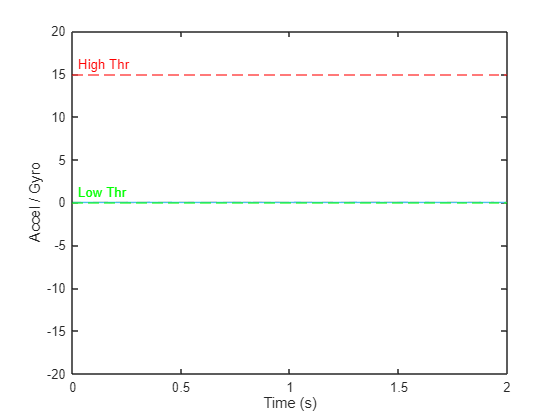

port        = "COM3";            
baud        = 115200;
s           = serialport(port, baud);
configureTerminator(s, "LF");
flush(s);

Fs          = 1e6/5000;
nyq         = Fs/2;

% butterworth bands-pass
[bBP,aBP]   = butter(2, [8 , 11]/nyq, 'bandpass');
ord         = max(length(aBP), length(bBP)) - 1;
ziBP        = zeros(ord, 3);      


[sampleData, Fs_sample] = audioread('assets_acoustic_tom.wav');
poolSize    = 8;
players     = cell(poolSize,1);
for i = 1:poolSize
    players{i} = audioplayer(sampleData, Fs_sample);
end
nextPlayer  = 1;


thr_high    = 15;    % trigger level 
thr_low     = 0;    % reset level (< thr_high)
armed       = true;   % only fire when armed


bufLen      = floor(2 * Fs);
dataBuf     = zeros(bufLen, 6);
tBuf        = (0:bufLen-1)'/Fs;


h = plot(tBuf, dataBuf);       
ylim([-20 20]);               
xlabel('Time (s)');
ylabel('Accel / Gyro');
yline(thr_high, 'r--', 'High Thr', 'LabelHorizontalAlignment','left');
yline(thr_low,  'g--', 'Low Thr',   'LabelHorizontalAlignment','left');


% the looppppsdaosjdainfwnvfiqweoibnv
idx = 1;
while ishandle(h(1))
    str      = readline(s);          
    vals     = sscanf(str, '%f,')';  
    accelRaw = vals(1:3);
    % Causal band-pass filter each accel axis—
    bpOut = zeros(1,3);
    for k = 1:3
        [bpOut(k), ziBP(:,k)] = filter(bBP, aBP, accelRaw(k), ziBP(:,k));
    end

    zFilt = bpOut(3);

    if armed && (zFilt > thr_high)
        play(players{nextPlayer});      
        nextPlayer = mod(nextPlayer, poolSize) + 1;
        armed = false;                 
    end
    if ~armed && (zFilt < thr_low)
        armed = true;                   
    end

    % dataBuf(idx,1:3) = bpOut;     
    dataBuf(idx,1:3) = accelRaw;
    for c = 1:6
        h(c).YData = dataBuf(:, c);
    end

    idx = idx + 1;
    if idx > bufLen
        idx = 1;
    end
end





